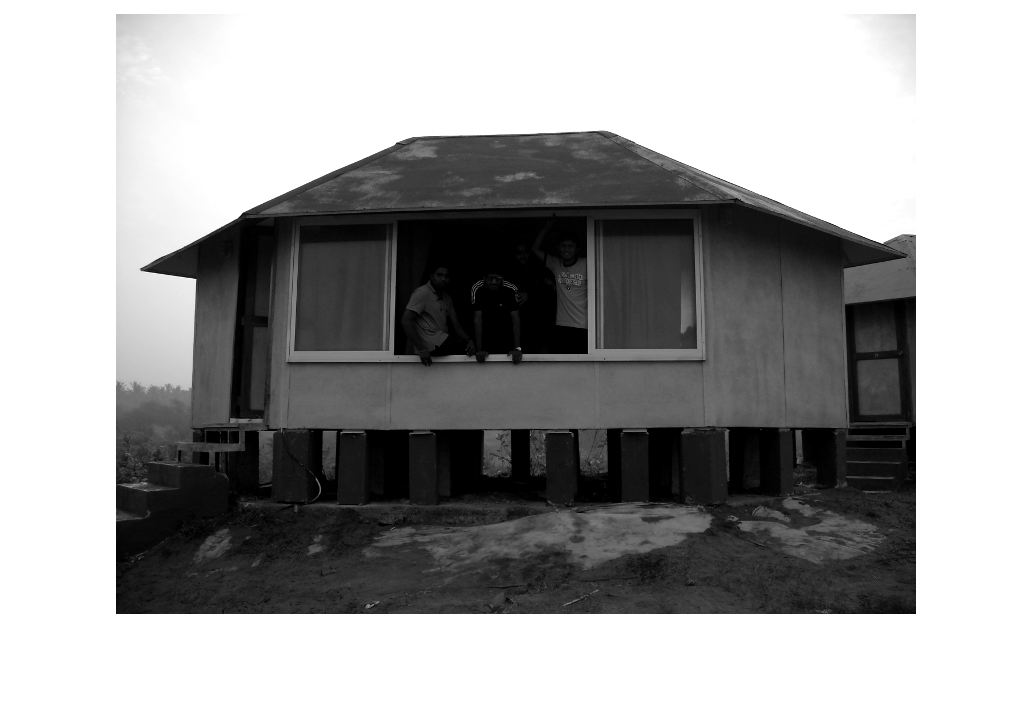

clear;clf;
img = imread("../images/man_in_house.png");
imshow(img)

[M, N] = size(img);

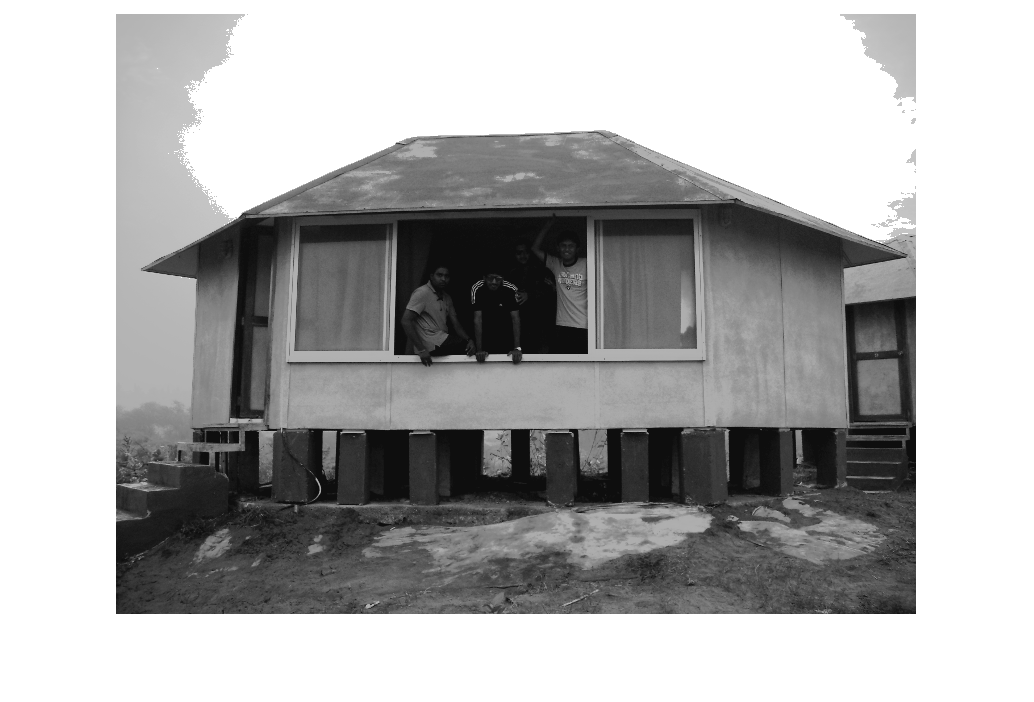

dist_img = zeros(256, 1);
result = zeros(size(img));
prefix_sum = 0;
for i = 0:255
    dist_img(i+1) = sum(sum(img == i)) / (M*N);
    prefix_sum = prefix_sum + dist_img(i+1);
    result(img == i) = round(255 * prefix_sum);
end
imshow(uint8(result))

p = 30;         % padding size
m = 2;          % block size to be updated  
w = m + 2 * p;  % window size
limit = 0.3;    % clipping limit

pad_img = padarray(img, [p, p], "symmetric", "pre");
pad_img = padarray(pad_img, [(floor(M/m)+1)*m+p-M, (floor(N/m)+1)*m+p-N],"symmetric", "post");
pad_result = zeros(size(pad_img));
tic
for i = 1:m:floor(M/m)*m+1
    for j = 1:m:floor(N/m)*m+1
        window = pad_img(i:i+w-1, j:j+w-1);
        upd_window = pad_img(i+p:i+p+m-1, j+p:j+p+m-1);
        dist_window = zeros(256, 1);
        map = zeros(256, 1);
        prefix_sum = 0;
        
%       Traversing the window to get the image distribution is more
%       memory-friendly than traversing intensity interval.

        for k = 1:w^2
            dist_window(window(k)+1) = dist_window(window(k)+1) + 1;
        end
        
        dist_window = dist_window / w^2;
        
        overflow_prob = 0;

%       count the total probability that need to clip
        for k = 1:256
            if dist_window(k) > limit
                overflow_prob = overflow_prob + dist_window(k) - limit;
                dist_window(k) = limit;
            end
        end

%       uniformly distribute those clipped probability

        dist_window = dist_window + overflow_prob / 256;

        for k = 0:255
            prefix_sum = prefix_sum + dist_window(k+1);
            map(k+1) = round(255 * prefix_sum);
        end

%       cache-friendly (logicial indexing is not efficient)

        for k = 1:m^2
            upd_window(k) = map(upd_window(k)+1); 
        end

        pad_result(i+p:i+p+m-1, j+p:j+p+m-1) = upd_window;
    end
end
result = pad_result(p+1: p+1+M, p+1: p+1+N);
toc

历时 2.585195 秒。


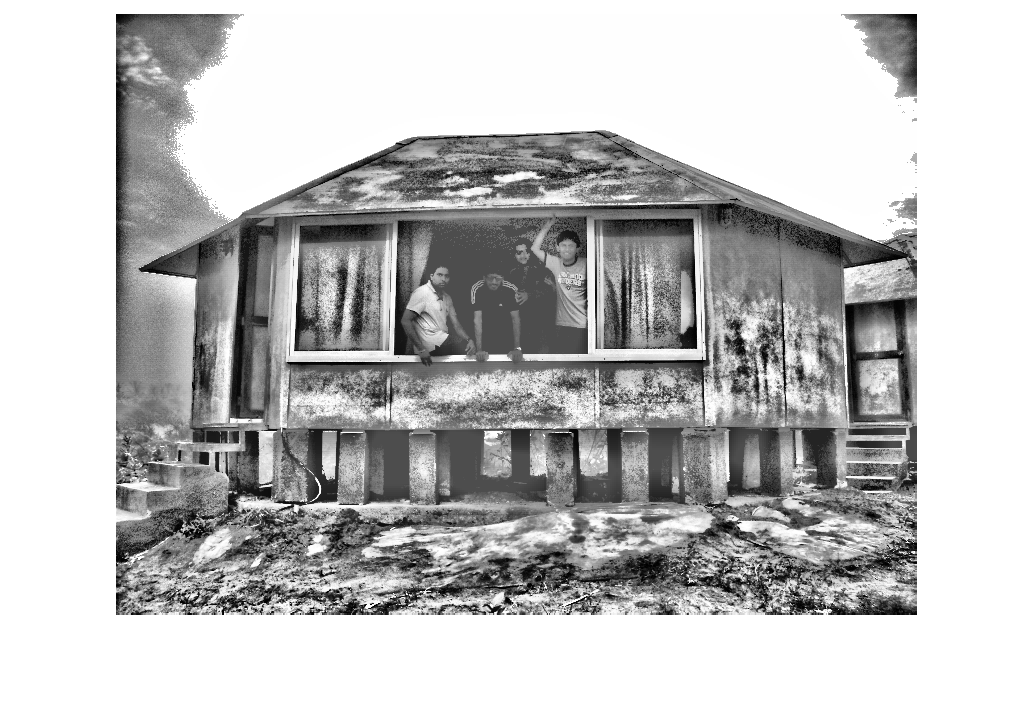

imshow(uint8(result))